## Análisis del puente Golden Gate

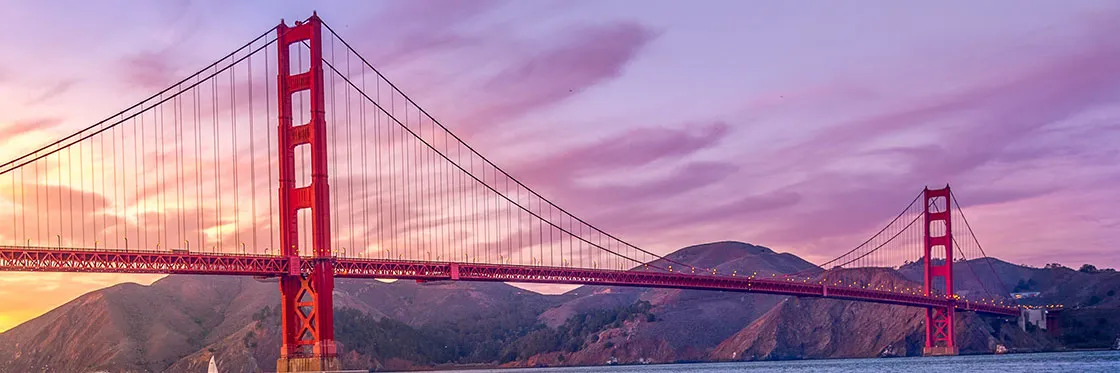

Factor de conversión

meters = 0.305 % pies a metros

meters = 0.3050

centimeters = 30.48 % pies a centimetros

centimeters = 30.4800

Inches = 12 % pies a pulgadas

Inches = 12

F = 1 % 

F = 1

Datos importantes

% Número de nodos en el cable principal
N = 250

N = 250

% Separación de los cables verticales (ft)
li = 50*F

li = 50

% Maxima distancia entre el punto más bajo y más alto del cable principal
MAX_CABLE_SAG = 472.2*F

MAX_CABLE_SAG = 472.2000

% Longitud del cable principal
LENGTH_MAIN_SPAN = 4200*F

LENGTH_MAIN_SPAN = 4200

% Fueza horizontal de cada cable (kips)
H = 53467 

H = 53467

% Peso (kips/ft)
W = 3.35

W = 3.3500

Ecuación de la catenaria

y = @(x)-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))

y = function_handle with value:
    @(x)-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))


biseccion(y, -100, 100, 10^3)

ans = 1001×8 table
    Iter     a          b            c           f(a)           f(b)          f(c)         error  
    ____    ____    _________    _________    ___________    __________    __________    _________

      0     -100          100            0    -6.7308e+44    6.7098e+44     -0.078319          100
      1        0          100           50      -0.078319    6.7098e+44    1.2941e+23           50
      2        0           50           25      -0.078319    1.2941e+23    1.7973e+12           25
      3        0           25         12.5      -0.078319    1.7973e+12    6.6979e+06         12.5
      4        0         12.5         6.25      -0.078319    6.6979e+06         12930         6.25
      5        

ans = 1.0e+44 *

         0   -0.0000    0.0000         0   -6.7308    6.7098   -0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    6.7098    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000         0    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000


Parece que una raiz de esta función no lineal es 0.0016. El cual es el coeficiente de la ecuación de la catenaria.

function z = biseccion(f, a, b, Maxiter)
    c = (a+b)/2;
    error = (b-a)/2;
    z = [0 a b c f(a) f(b) f(c) error];
    for k=1:Maxiter
        if f(a)*f(c)<0
            b = c;
        else
            a = c;
        end
        c = (a+b)/2;
        error=(b-a)/2;
        z = [z; k a b c f(a) f(b) f(c) error];
    end
    array2table(z, "VariableNames", ["Iter", "a", "b", "c", "f(a)", "f(b)", "f(c)", "error"])
end